# Bicycle model Simulink experiment

clear; clc;

### Load environment

open_system('RLBicycleSimulinkModel.slx')

load exampleMaps.mat;

chosenMap = QCarMap;
map = binaryOccupancyMap(chosenMap)

map =   binaryOccupancyMap with properties:

   mapLayer Properties
              LayerName: 'binaryLayer'
               DataType: 'logical'
           DefaultValue: 0
    GridLocationInWorld: [0 0]
      GridOriginInLocal: [0 0]
     LocalOriginInWorld: [0 0]
             Resolution: 1
               GridSize: [20 20]
           XLocalLimits: [0 20]
           YLocalLimits: [0 20]
           XWorldLimits: [0 20]
           YWorldLimits: [0 20]



startLoc = randLoc(chosenMap);
startOrient = rand*2*pi;

### Setup DDPG Agent

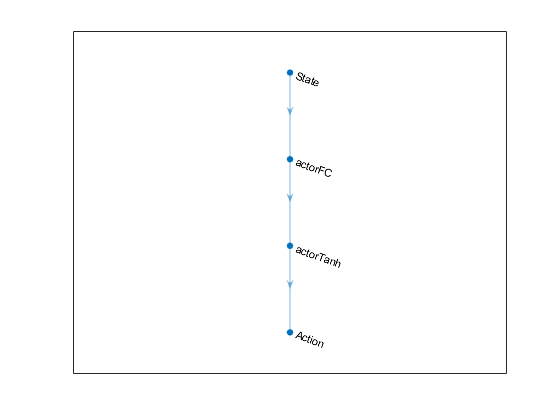

% Setup environnement
obsInfo = rlNumericSpec([1 1],...
    'LowerLimit',[0]',...
    'UpperLimit',[5]');
obsInfo.Name = 'observation';
obsInfo.Description = 'minimum distance to wall';
numObservations = obsInfo.Dimension(1);

actInfo = rlNumericSpec([2 1]);
actInfo.Name = 'actions';
actInfo.Description = 'speed, steering';
numActions = actInfo.Dimension(1);

env = rlSimulinkEnv('RLBicycleSimulinkModel','RLBicycleSimulinkModel/RL Agent',...
    obsInfo,actInfo);

env.ResetFcn = @(in)localResetFcn(in, chosenMap);
Ts = 1.0;
Tf = 200;
rng(0)

% Setup acteur
actorNetwork = [
    featureInputLayer(numObservations,'Normalization','none','Name','State')
    fullyConnectedLayer(3, 'Name','actorFC')
    tanhLayer('Name','actorTanh')
    fullyConnectedLayer(numActions,'Name','Action')
    ];

actorPlot = layerGraph();
actorPlot = addLayers(actorPlot,actorNetwork);

figure
plot(actorPlot)

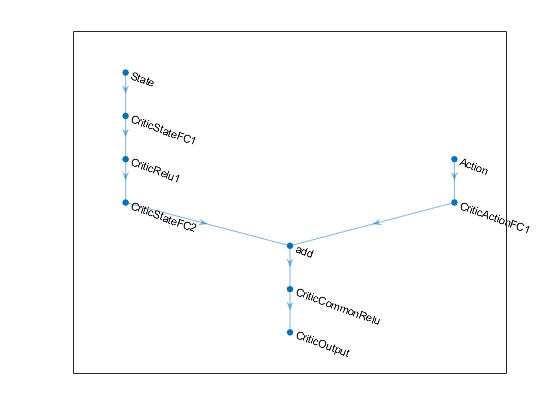


actorOptions = rlRepresentationOptions('LearnRate',1e-04,'GradientThreshold',1);
actor = rlDeterministicActorRepresentation(actorNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},actorOptions);

% Setup critique
statePath = [
    featureInputLayer(numObservations,'Normalization','none','Name','State')
    fullyConnectedLayer(50,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(25,'Name','CriticStateFC2')];
actionPath = [
    featureInputLayer(numActions,'Normalization','none','Name','Action')
    fullyConnectedLayer(25,'Name','CriticActionFC1')];
commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1,'Name','CriticOutput')];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');

figure
plot(criticNetwork)


criticOpts = rlRepresentationOptions('LearnRate',1e-04,'GradientThreshold',1);

critic = rlQValueRepresentation(criticNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},criticOpts);

%Setup agent
agentOpts = rlDDPGAgentOptions(...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...
    'DiscountFactor',1.0, ...
    'MiniBatchSize',64, ...
    'ExperienceBufferLength',1e6); 
agentOpts.NoiseOptions.StandardDeviation = 0.3;
agentOpts.NoiseOptions.StandardDeviationDecayRate = 1e-5;

agent = rlDDPGAgent(actor,critic,agentOpts);

### Train agent

% Parametres surement a changer
maxepisodes = 5000;
maxsteps = ceil(Tf/Ts);
trainOpts = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes, ...
    'MaxStepsPerEpisode',maxsteps, ...
    'ScoreAveragingWindowLength',20, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',800);

doTraining = true;

if doTraining
    % Train the agent.
    reinforcementLearningDesigner
    trainingStats = train(agent,env,trainOpts);
else
    % Load the pretrained agent for the example.
    load('RLBicycle.mat','agent')
end

sprintLoc = '[1.5         8.5      5.1939]'

sprintLoc = '[16.5         17.5      5.85035]'

sprintLoc = '[17.5         11.5      3.16572]'

sprintLoc = '[12.5         16.5      3.34196]'

sprintLoc = '[12.5         13.5      4.52493]'

sprintLoc = '[6.5         10.5      3.49782]'

sprintLoc = '[3.5         11.5      4.36558]'

sprintLoc = '[14.5          7.5       2.8539]'

sprintLoc = '[14.5          8.5      4.35898]'

sprintLoc = '[18.5         15.5      4.43324]'

sprintLoc = '[2.5         7.5      3.7128]'

sprintLoc = '[4.5         16.5    0.0982985]'

sprintLoc = '[13.5         10.5       1.3697]'

sprintLoc = '[11.5          2.5      4.21706]'

sprintLoc = '[11.5          1.5     0.354014]'

sprintLoc = '[12.5         10.5      5.42784]'

sprintLoc = '[2.5         10.5     0.899476]'

sprintLoc = '[10.5          5.5     0.633034]'

sprintLoc = '[10.5         11.5      4.79336]'

sprintLoc = '[1.5         13.5      3.24827]'

sprintLoc = '[3.5         18.5      3.71012]'

sprintLoc = '[8.5         18.5      4.12123]'

sprintLoc = '[10.5         11.5      4.27298]'

sprintLoc = '[7.5         4.5      3.6375]'

sprintLoc = '[17.5          8.5     0.707582]'

sprintLoc = '[8.5         6.5       2.522]'

sprintLoc = '[16.5          8.5      2.45155]'

sprintLoc = '[7.5         2.5      1.6344]'

sprintLoc = '[1.5         8.5      1.6166]'

sprintLoc = '[5.5         8.5       0.749]'

sprintLoc = '[4.5         15.5     0.465519]'

sprintLoc = '[18.5         18.5      1.38974]'

sprintLoc = '[9.5         7.5       3.291]'

sprintLoc = '[8.5         3.5     0.16404]'

sprintLoc = '[14.5         12.5      3.47027]'

sprintLoc = '[4.5         15.5      1.43274]'

sprintLoc = '[17.5          8.5      1.99817]'

sprintLoc = '[12.5         18.5      5.71203]'

sprintLoc = '[17.5          8.5      5.68223]'

sprintLoc = '[14.5          3.5       2.1145]'

sprintLoc = '[3.5         6.5      2.5375]'

sprintLoc = '[11.5          5.5       1.5174]'

sprintLoc = '[16.5         14.5      1.10466]'

sprintLoc = '[7.5         3.5   0.0075297]'

sprintLoc = '[6.5         13.5      3.92859]'

sprintLoc = '[10.5          8.5      1.80596]'

sprintLoc = '[14.5         12.5     0.774211]'

sprintLoc = '[3.5         13.5      2.71126]'

sprintLoc = '[13.5          5.5    0.0613154]'

sprintLoc = '[10.5          5.5      5.94534]'

sprintLoc = '[18.5          7.5      0.15617]'

sprintLoc = '[13.5         16.5      6.10411]'

sprintLoc = '[1.5         9.5      3.6598]'

sprintLoc = '[13.5         14.5      4.08433]'

sprintLoc = '[14.5          7.5      3.65419]'

sprintLoc = '[6.5         18.5      2.45464]'

sprintLoc = '[7.5         7.5     0.82382]'

sprintLoc = '[8.5         1.5      3.8618]'

sprintLoc = '[15.5          4.5      2.81499]'

sprintLoc = '[11.5          1.5      3.11828]'

sprintLoc = '[12.5          4.5      5.25938]'

sprintLoc = '[10.5          5.5      4.69113]'

sprintLoc = '[12.5         12.5      1.08451]'

sprintLoc = '[17.5         18.5      4.39593]'

sprintLoc = '[14.5          4.5      3.61945]'

sprintLoc = '[16.5          8.5      6.21055]'

sprintLoc = '[10.5          1.5      4.55963]'

sprintLoc = '[11.5         10.5      5.21493]'

sprintLoc = '[17.5         15.5        1.997]'

sprintLoc = '[5.5         10.5      6.11135]'

sprintLoc = '[5.5         17.5      5.72805]'

sprintLoc = '[12.5          5.5     0.557104]'

sprintLoc = '[16.5         11.5      5.95714]'

sprintLoc = '[1.5         11.5      1.79139]'

sprintLoc = '[16.5          3.5       2.7805]'

sprintLoc = '[13.5          4.5      1.99871]'

sprintLoc = '[2.5         13.5      3.58764]'

sprintLoc = '[9.5         18.5      3.46942]'

sprintLoc = '[16.5          9.5      2.40424]'

sprintLoc = '[15.5          7.5      3.34485]'

sprintLoc = '[14.5         17.5      2.06522]'

sprintLoc = '[1.5         11.5      2.60053]'

sprintLoc = '[6.5         5.5      4.7675]'

sprintLoc = '[15.5          3.5      6.23518]'

sprintLoc = '[16.5          8.5      4.57959]'

sprintLoc = '[11.5         18.5      1.21747]'

sprintLoc = '[3.5         9.5      3.2537]'

sprintLoc = '[8.5         18.5      3.01269]'

sprintLoc = '[4.5         7.5      4.4301]'

sprintLoc = '[11.5         15.5      6.25479]'

sprintLoc = '[11.5         10.5      5.66246]'

sprintLoc = '[10.5          8.5      3.40968]'

sprintLoc = '[6.5         17.5      2.96002]'

sprintLoc = '[8.5         3.5      6.0879]'

sprintLoc = '[12.5          7.5       5.5115]'

sprintLoc = '[15.5          9.5      5.11437]'

sprintLoc = '[17.5          8.5      2.10065]'

sprintLoc = '[11.5         18.5      4.41121]'

sprintLoc = '[1.5         9.5    0.058638]'

sprintLoc = '[18.5         12.5   0.00891621]'

sprintLoc = '[8.5         8.5     0.30922]'

sprintLoc = '[11.5          4.5      5.28648]'

sprintLoc = '[4.5         10.5      4.78848]'

sprintLoc = '[12.5         18.5      1.01519]'

sprintLoc = '[14.5         11.5       2.7225]'

sprintLoc = '[17.5          7.5      1.12453]'

sprintLoc = '[12.5         12.5      2.06052]'

sprintLoc = '[12.5          2.5      2.56014]'

sprintLoc = '[7.5         4.5      2.7705]'

sprintLoc = '[2.5         13.5      5.71427]'

sprintLoc = '[12.5         17.5      1.21538]'

sprintLoc = '[15.5          6.5       2.6303]'

sprintLoc = '[3.5         16.5      3.92651]'

sprintLoc = '[14.5         16.5     0.422372]'

sprintLoc = '[15.5         14.5      5.22214]'

sprintLoc = '[3.5         9.5      3.8836]'

sprintLoc = '[17.5         11.5      3.66151]'

sprintLoc = '[17.5          8.5     0.228595]'

sprintLoc = '[14.5          3.5     0.904203]'

sprintLoc = '[12.5          5.5      2.03672]'

sprintLoc = '[8.5         8.5      2.4265]'

sprintLoc = '[12.5          3.5      1.18182]'

sprintLoc = '[15.5          4.5      4.65185]'

sprintLoc = '[13.5         16.5      5.20234]'

sprintLoc = '[5.5         6.5      3.2863]'

sprintLoc = '[6.5         16.5      5.09123]'

sprintLoc = '[11.5          5.5      4.27612]'

sprintLoc = '[7.5         10.5      6.23106]'

sprintLoc = '[4.5         10.5     0.323182]'

sprintLoc = '[18.5          8.5   0.00214547]'

sprintLoc = '[10.5          4.5       1.3778]'

sprintLoc = '[14.5         14.5      3.41365]'

sprintLoc = '[6.5         16.5      3.47191]'

sprintLoc = '[7.5         10.5      2.17827]'

sprintLoc = '[12.5         15.5      4.68647]'

sprintLoc = '[14.5         15.5      2.30773]'

sprintLoc = '[14.5         17.5      1.52432]'

sprintLoc = '[7.5         5.5      5.8276]'

sprintLoc = '[1.5         11.5      1.02352]'

sprintLoc = '[16.5          3.5      3.15542]'

sprintLoc = '[7.5         6.5      1.4426]'

sprintLoc = '[12.5         16.5      1.46387]'

sprintLoc = '[18.5         15.5      5.19274]'

sprintLoc = '[11.5         15.5      2.06743]'

sprintLoc = '[4.5         6.5      3.6727]'

sprintLoc = '[16.5          5.5      2.52932]'

sprintLoc = '[17.5         12.5      6.22782]'

sprintLoc = '[4.5         16.5      4.24656]'

sprintLoc = '[7.5         11.5      5.02983]'

sprintLoc = '[16.5          7.5      2.70221]'

sprintLoc = '[11.5         14.5      4.66508]'

sprintLoc = '[15.5          7.5      2.69739]'

sprintLoc = '[16.5          5.5      3.91017]'

sprintLoc = '[1.5         10.5      3.27724]'

sprintLoc = '[17.5          8.5      4.91171]'

sprintLoc = '[2.5         12.5      1.63755]'

sprintLoc = '[3.5         6.5      3.0366]'

sprintLoc = '[6.5         15.5      6.20457]'

sprintLoc = '[14.5          7.5      6.11797]'

sprintLoc = '[17.5          8.5      3.97054]'

sprintLoc = '[18.5         14.5       3.0413]'

sprintLoc = '[12.5         17.5       1.2487]'

sprintLoc = '[14.5         13.5      3.28807]'

sprintLoc = '[13.5         10.5       0.3709]'

sprintLoc = '[17.5          6.5      1.44326]'

sprintLoc = '[4.5         13.5     0.415696]'

sprintLoc = '[5.5         5.5      5.5296]'

sprintLoc = '[12.5         15.5     0.715847]'

sprintLoc = '[1.5         9.5      2.0461]'

sprintLoc = '[12.5          4.5      3.64352]'

sprintLoc = '[12.5         11.5      2.81756]'

sprintLoc = '[8.5         2.5      2.8895]'

sprintLoc = '[9.5         11.5       5.0605]'

sprintLoc = '[14.5         17.5     0.327933]'

sprintLoc = '[1.5         14.5      3.18428]'

sprintLoc = '[3.5         8.5      1.0599]'

sprintLoc = '[15.5          7.5      5.91762]'

sprintLoc = '[12.5         10.5      4.08726]'

sprintLoc = '[11.5         12.5      4.09205]'

sprintLoc = '[13.5          4.5      3.41353]'

sprintLoc = '[8.5         1.5     0.36028]'

sprintLoc = '[12.5         15.5      4.34288]'

sprintLoc = '[6.5         18.5      3.26845]'

sprintLoc = '[4.5         15.5      5.74401]'

sprintLoc = '[15.5          5.5     0.954075]'

sprintLoc = '[16.5         15.5      1.70168]'

sprintLoc = '[4.5         6.5      5.2123]'

sprintLoc = '[16.5         11.5      3.59291]'

sprintLoc = '[5.5         13.5      5.00304]'

sprintLoc = '[8.5         8.5      2.9258]'

sprintLoc = '[5.5         13.5      5.67789]'

sprintLoc = '[18.5         14.5      1.63684]'

sprintLoc = '[14.5         18.5      3.09534]'

sprintLoc = '[13.5         17.5      3.38366]'

sprintLoc = '[6.5         17.5      3.13939]'

sprintLoc = '[12.5         11.5      4.38726]'

sprintLoc = '[6.5         16.5       1.5461]'

sprintLoc = '[11.5         18.5     0.300256]'

sprintLoc = '[13.5         11.5     0.716472]'

sprintLoc = '[14.5         13.5      3.24382]'

sprintLoc = '[6.5         13.5     0.738686]'

sprintLoc = '[2.5         9.5      4.1261]'

sprintLoc = '[5.5         15.5      3.50676]'

sprintLoc = '[8.5         5.5      4.7359]'

sprintLoc = '[17.5         14.5      2.55619]'

sprintLoc = '[18.5          5.5      3.34996]'

sprintLoc = '[5.5         18.5     0.430916]'

sprintLoc = '[5.5         11.5      1.27737]'

sprintLoc = '[12.5         15.5      3.15228]'

sprintLoc = '[13.5         15.5      1.46633]'

sprintLoc = '[12.5          2.5      3.24065]'

sprintLoc = '[16.5         18.5      3.13046]'

sprintLoc = '[5.5         13.5      5.76356]'

sprintLoc = '[5.5         7.5      2.6437]'

sprintLoc = '[6.5         13.5     0.577248]'

sprintLoc = '[8.5         5.5      1.9258]'

sprintLoc = '[11.5         17.5     0.265486]'

sprintLoc = '[10.5          8.5      1.09059]'

sprintLoc = '[11.5         12.5       1.3474]'

sprintLoc = '[5.5         16.5      2.17714]'

sprintLoc = '[1.5         10.5      2.30488]'

sprintLoc = '[14.5         10.5      5.05495]'

sprintLoc = '[16.5          3.5     0.777189]'

sprintLoc = '[16.5         12.5     0.101284]'

sprintLoc = '[15.5         17.5      2.40563]'

sprintLoc = '[1.5         14.5      2.08595]'

sprintLoc = '[16.5          7.5      5.20383]'

sprintLoc = '[13.5         14.5      2.74684]'

sprintLoc = '[7.5         8.5     0.98525]'

sprintLoc = '[6.5         6.5      5.6203]'

sprintLoc = '[4.5         6.5       2.569]'

sprintLoc = '[15.5         14.5      1.34782]'

sprintLoc = '[13.5         11.5      5.34497]'

sprintLoc = '[11.5         18.5      2.63591]'

sprintLoc = '[5.5         18.5      2.93272]'

sprintLoc = '[5.5         8.5      4.4141]'

sprintLoc = '[8.5         3.5        5.38]'

sprintLoc = '[11.5          7.5      1.39295]'

sprintLoc = '[4.5         10.5      2.72328]'

sprintLoc = '[3.5         12.5      3.41205]'

sprintLoc = '[15.5         15.5      2.64566]'

sprintLoc = '[1.5         11.5      1.09425]'

sprintLoc = '[14.5         10.5      1.59005]'

sprintLoc = '[18.5         15.5      5.57338]'

sprintLoc = '[14.5         13.5      4.88199]'

sprintLoc = '[10.5          8.5      3.84052]'

sprintLoc = '[10.5          5.5      4.42317]'

sprintLoc = '[7.5         11.5      5.57859]'

sprintLoc = '[16.5         17.5      5.89993]'

sprintLoc = '[8.5         6.5      3.4014]'

sprintLoc = '[18.5          5.5      2.12425]'

sprintLoc = '[17.5          6.5     0.867836]'

sprintLoc = '[12.5          9.5      2.97583]'

sprintLoc = '[5.5         8.5      3.6918]'

sprintLoc = '[17.5          9.5      2.74838]'

sprintLoc = '[14.5          9.5      5.40874]'

sprintLoc = '[17.5          4.5      5.41357]'

sprintLoc = '[14.5         17.5      5.89364]'

sprintLoc = '[2.5         7.5      6.1611]'

sprintLoc = '[12.5         17.5      3.02994]'

sprintLoc = '[4.5         10.5      4.55526]'

sprintLoc = '[12.5         11.5      2.72335]'

sprintLoc = '[4.5         8.5    0.063947]'

sprintLoc = '[17.5          4.5     0.056015]'

sprintLoc = '[7.5         11.5       3.6768]'

sprintLoc = '[13.5         12.5      2.72294]'

sprintLoc = '[4.5         13.5      5.38704]'

sprintLoc = '[10.5         18.5      2.01987]'

sprintLoc = '[16.5         12.5      4.96133]'

sprintLoc = '[5.5         13.5       3.0766]'

sprintLoc = '[11.5          5.5      1.60919]'

sprintLoc = '[17.5          8.5        5.127]'

sprintLoc = '[14.5         16.5     0.218867]'

sprintLoc = '[6.5         12.5      2.15517]'

sprintLoc = '[4.5         15.5      4.54331]'

sprintLoc = '[5.5         11.5      2.64526]'

sprintLoc = '[6.5         5.5      1.0738]'

sprintLoc = '[4.5         13.5      2.78387]'

sprintLoc = '[8.5         3.5      1.2139]'

sprintLoc = '[12.5          5.5      3.51656]'

sprintLoc = '[18.5         14.5      4.26766]'

sprintLoc = '[12.5         18.5     0.374739]'

sprintLoc = '[15.5          9.5      4.27822]'

sprintLoc = '[8.5         7.5        1.34]'

sprintLoc = '[16.5          8.5      2.90295]'

sprintLoc = '[10.5         18.5      4.64341]'

sprintLoc = '[12.5          7.5      2.99441]'

sprintLoc = '[3.5         9.5      3.4117]'

sprintLoc = '[1.5         13.5      5.58974]'

sprintLoc = '[2.5         8.5      1.7607]'

sprintLoc = '[4.5         10.5      5.49743]'

sprintLoc = '[17.5          4.5     0.483674]'

sprintLoc = '[9.5         8.5      3.1588]'

sprintLoc = '[17.5         12.5      1.66694]'

sprintLoc = '[6.5         8.5      3.3111]'

sprintLoc = '[17.5         15.5      0.43585]'

sprintLoc = '[5.5         7.5      5.4329]'

sprintLoc = '[8.5         4.5      3.7552]'

sprintLoc = '[14.5         14.5      5.65304]'

sprintLoc = '[10.5          7.5      1.42402]'

sprintLoc = '[10.5          5.5     0.429587]'

sprintLoc = '[8.5         2.5      2.7836]'

sprintLoc = '[17.5          7.5     0.755101]'

sprintLoc = '[11.5         17.5      2.19016]'

sprintLoc = '[1.5         14.5      2.86843]'

sprintLoc = '[13.5         13.5      3.58994]'

sprintLoc = '[12.5         17.5      4.16168]'

sprintLoc = '[17.5          9.5      0.88804]'

sprintLoc = '[1.5         14.5      1.93513]'

sprintLoc = '[13.5         13.5      3.33668]'

sprintLoc = '[14.5         10.5      3.06619]'

sprintLoc = '[9.5         18.5      2.44593]'

sprintLoc = '[13.5         16.5       6.0956]'

sprintLoc = '[4.5         15.5      3.67003]'

sprintLoc = '[8.5         10.5      3.11422]'

sprintLoc = '[13.5         14.5      1.89723]'

sprintLoc = '[18.5         17.5      6.28188]'

sprintLoc = '[18.5         11.5      2.71096]'

sprintLoc = '[6.5         14.5    0.0858005]'

sprintLoc = '[7.5         18.5      3.43363]'

sprintLoc = '[8.5         4.5      1.2142]'

sprintLoc = '[16.5         14.5      3.32849]'

sprintLoc = '[11.5          4.5      3.69339]'

sprintLoc = '[13.5         12.5      1.38014]'

sprintLoc = '[11.5          2.5       1.0631]'

sprintLoc = '[4.5         16.5      5.11194]'

sprintLoc = '[7.5         18.5      4.27478]'

sprintLoc = '[4.5         11.5      6.16838]'

sprintLoc = '[16.5          5.5      4.28801]'

sprintLoc = '[8.5         7.5      3.0065]'

sprintLoc = '[11.5          2.5      5.68836]'

sprintLoc = '[12.5          3.5      3.55572]'

sprintLoc = '[18.5         15.5       4.3083]'

sprintLoc = '[11.5          4.5      2.00623]'

sprintLoc = '[18.5         17.5      4.99255]'

sprintLoc = '[18.5          3.5      3.25181]'

sprintLoc = '[12.5         18.5      4.17184]'

sprintLoc = '[16.5         12.5     0.534052]'

sprintLoc = '[10.5          2.5      2.38851]'

sprintLoc = '[16.5          4.5      5.55699]'

sprintLoc = '[14.5          7.5      1.56401]'

sprintLoc = '[5.5         15.5     0.313291]'

sprintLoc = '[13.5         12.5      4.69156]'

sprintLoc = '[5.5         17.5      5.06485]'

sprintLoc = '[11.5          3.5       3.3407]'

sprintLoc = '[7.5         6.5      4.5663]'

sprintLoc = '[4.5         13.5     0.329776]'

sprintLoc = '[2.5         7.5      3.9106]'

sprintLoc = '[1.5         14.5      2.64145]'

sprintLoc = '[16.5          7.5      2.00476]'

sprintLoc = '[8.5         1.5      4.6154]'

sprintLoc = '[12.5          1.5     0.757175]'

sprintLoc = '[9.5         11.5      3.10676]'

sprintLoc = '[5.5         5.5      3.7334]'

sprintLoc = '[9.5         7.5      4.1193]'

sprintLoc = '[18.5         12.5      1.77714]'

sprintLoc = '[4.5         8.5     0.17122]'

sprintLoc = '[17.5         12.5      1.27921]'

sprintLoc = '[10.5          1.5      5.41728]'

sprintLoc = '[8.5         10.5      3.56169]'

sprintLoc = '[13.5          7.5     0.491525]'

sprintLoc = '[4.5         5.5      4.7688]'

sprintLoc = '[11.5          8.5      4.59124]'

sprintLoc = '[2.5         9.5      4.0979]'

sprintLoc = '[16.5          6.5      2.52812]'

sprintLoc = '[17.5         14.5      1.51973]'

sprintLoc = '[15.5          5.5       1.7432]'

sprintLoc = '[8.5         6.5      1.8275]'

sprintLoc = '[4.5         18.5      5.40473]'

sprintLoc = '[11.5          9.5      1.69528]'

sprintLoc = '[6.5         14.5      4.04867]'

sprintLoc = '[10.5          5.5      3.63528]'

sprintLoc = '[18.5         17.5      3.03168]'

sprintLoc = '[8.5         6.5     0.34755]'

sprintLoc = '[7.5         7.5      5.5639]'

sprintLoc = '[5.5         5.5      3.0686]'

sprintLoc = '[14.5          4.5       1.3589]'

sprintLoc = '[17.5          3.5    0.0113055]'

sprintLoc = '[14.5         17.5     0.743351]'

sprintLoc = '[12.5         10.5    0.0471704]'

sprintLoc = '[13.5         18.5      5.48859]'

sprintLoc = '[2.5         7.5      1.5201]'

sprintLoc = '[11.5         12.5      1.89004]'

sprintLoc = '[15.5         15.5      4.90775]'

sprintLoc = '[18.5          9.5      5.35205]'

sprintLoc = '[16.5          3.5       1.5532]'

sprintLoc = '[3.5         12.5      3.61368]'

sprintLoc = '[15.5          3.5      2.24176]'

sprintLoc = '[6.5         5.5    0.037768]'

sprintLoc = '[16.5          9.5      3.37937]'

sprintLoc = '[17.5         14.5      4.19771]'

sprintLoc = '[3.5         11.5      6.03107]'

sprintLoc = '[11.5         16.5        6.186]'

sprintLoc = '[17.5          4.5     0.217587]'

sprintLoc = '[4.5         7.5      2.7108]'

sprintLoc = '[9.5         7.5      5.8174]'

sprintLoc = '[14.5         14.5      5.94965]'

sprintLoc = '[8.5         4.5       2.032]'

sprintLoc = '[2.5         7.5      2.0728]'

sprintLoc = '[6.5         16.5      3.34068]'

sprintLoc = '[2.5         12.5      2.17806]'

sprintLoc = '[6.5         11.5      5.42828]'

sprintLoc = '[3.5         13.5      5.66637]'

sprintLoc = '[10.5          5.5      3.35496]'

sprintLoc = '[11.5          8.5    0.0927628]'

sprintLoc = '[14.5         10.5      2.39557]'

sprintLoc = '[16.5          7.5     0.336623]'

sprintLoc = '[3.5         18.5      2.00563]'

sprintLoc = '[6.5         4.5      4.8206]'

sprintLoc = '[18.5         14.5      4.71143]'

sprintLoc = '[8.5         4.5      3.2726]'

sprintLoc = '[4.5         16.5      4.16533]'

sprintLoc = '[16.5         15.5      2.94747]'

sprintLoc = '[6.5         13.5      6.20058]'

sprintLoc = '[14.5         11.5      4.73045]'

sprintLoc = '[1.5         10.5      2.53193]'

sprintLoc = '[2.5         14.5      3.85588]'

sprintLoc = '[16.5         11.5      5.93151]'

sprintLoc = '[15.5          9.5      5.20751]'

sprintLoc = '[18.5          6.5      5.05212]'

sprintLoc = '[10.5          9.5      5.15693]'

sprintLoc = '[14.5          4.5      2.50633]'

sprintLoc = '[5.5         16.5      6.25412]'

sprintLoc = '[12.5         14.5      5.85783]'

sprintLoc = '[13.5         11.5      2.39294]'

sprintLoc = '[12.5          7.5      2.56115]'

sprintLoc = '[10.5         18.5      1.29704]'

sprintLoc = '[6.5         11.5      3.05949]'

sprintLoc = '[5.5         11.5       5.5187]'

sprintLoc = '[1.5         8.5     0.52941]'

sprintLoc = '[11.5         10.5      4.82585]'

sprintLoc = '[4.5         11.5      2.88382]'

sprintLoc = '[7.5         6.5      1.5942]'

sprintLoc = '[3.5         7.5      4.6598]'

sprintLoc = '[14.5         14.5    0.0391178]'

sprintLoc = '[7.5         18.5      2.00022]'

sprintLoc = '[11.5          5.5     0.785489]'

sprintLoc = '[4.5         6.5      6.1855]'

sprintLoc = '[16.5          3.5      5.67433]'

sprintLoc = '[2.5         14.5      4.58278]'

sprintLoc = '[8.5         10.5      3.33317]'

sprintLoc = '[10.5          5.5      3.02159]'

sprintLoc = '[13.5          4.5      3.82119]'

sprintLoc = '[6.5         17.5     0.838143]'

sprintLoc = '[16.5         15.5      4.47809]'

sprintLoc = '[6.5         15.5      1.48526]'

sprintLoc = '[12.5         12.5     0.770469]'

sprintLoc = '[14.5          8.5      5.20865]'

sprintLoc = '[18.5          7.5     0.328054]'

sprintLoc = '[11.5         14.5      2.01215]'

sprintLoc = '[18.5          9.5       3.3929]'

sprintLoc = '[15.5          3.5      5.62419]'

sprintLoc = '[13.5         13.5      6.22275]'

sprintLoc = '[9.5         11.5     0.523199]'

sprintLoc = '[11.5         14.5      3.06563]'

sprintLoc = '[12.5          4.5      4.05679]'

sprintLoc = '[7.5         2.5       2.372]'

sprintLoc = '[5.5         4.5      3.9139]'

sprintLoc = '[10.5          8.5      1.36843]'

sprintLoc = '[17.5         17.5      1.78404]'

sprintLoc = '[12.5         15.5      5.99948]'

sprintLoc = '[18.5          7.5      1.02192]'

sprintLoc = '[3.5         7.5      5.3266]'

sprintLoc = '[11.5         11.5      5.81721]'

sprintLoc = '[16.5         12.5      3.01539]'

sprintLoc = '[5.5         5.5      3.0223]'

sprintLoc = '[3.5         12.5      5.17548]'

sprintLoc = '[14.5         17.5       4.9077]'

sprintLoc = '[1.5         13.5      1.35199]'

sprintLoc = '[4.5         6.5      1.2432]'

sprintLoc = '[7.5         11.5      3.81099]'

sprintLoc = '[14.5          8.5      5.39531]'

sprintLoc = '[18.5         15.5      1.79443]'

sprintLoc = '[14.5          7.5      4.57845]'

sprintLoc = '[8.5         8.5      6.0265]'

sprintLoc = '[7.5         10.5      3.58302]'

sprintLoc = '[5.5         13.5       6.0586]'

sprintLoc = '[13.5          5.5      3.33717]'

sprintLoc = '[8.5         6.5      5.9727]'

sprintLoc = '[1.5         11.5     0.961759]'

sprintLoc = '[1.5         11.5      1.80337]'

sprintLoc = '[17.5          6.5      6.04283]'

sprintLoc = '[18.5         12.5      4.41166]'

sprintLoc = '[14.5          7.5      1.58024]'

sprintLoc = '[12.5          5.5      3.25382]'

sprintLoc = '[4.5         5.5       4.087]'

sprintLoc = '[17.5         17.5      1.31894]'

sprintLoc = '[12.5          3.5      5.19116]'

sprintLoc = '[13.5         10.5      1.57915]'

sprintLoc = '[15.5         17.5      2.96711]'

sprintLoc = '[3.5         16.5      2.99399]'

sprintLoc = '[12.5          1.5      5.70789]'

sprintLoc = '[7.5         10.5      4.79718]'

sprintLoc = '[14.5          9.5      3.65867]'

sprintLoc = '[6.5         3.5      2.5082]'

sprintLoc = '[18.5          4.5      2.26827]'

sprintLoc = '[18.5         14.5      2.40643]'

sprintLoc = '[5.5         13.5      5.53207]'

sprintLoc = '[5.5         17.5      1.23324]'

### Validation : Run model

simulation = sim('RLBicycleSimulinkModel.slx');

#### Get all robot poses

robotPose = simulation.BicyclePose

#### Print map of movements

numRobots = size(robotPose, 2) / 3;
thetaIdx = 3;

% Translation
xyz = robotPose;
xyz(:, thetaIdx) = 0;

% Rotation in XYZ euler angles
theta = robotPose(:,thetaIdx);
thetaEuler = zeros(size(robotPose, 1), 3 * size(theta, 2));
thetaEuler(:, end) = theta;

show(map)
hold on;

% Plot Start Location
plotTransforms([startLoc, 0], eul2quat([0, 0, 0]))
text(startLoc(1), startLoc(2), 2, 'Start');

% Plot Goal Location
plotTransforms([goalLoc, 0], eul2quat([0, 0, 0]))
text(goalLoc(1), goalLoc(2), 2, 'Goal');

% Plot Robot's XY locations
plot(robotPose(:, 1), robotPose(:, 2), 'b')

% Plot Robot's pose as it traverses the path
quat = eul2quat(thetaEuler(size(xyz, 1), :), 'xyz');
plotTransforms(xyz(size(xyz, 1),:), quat, 'MeshFilePath',...
    'groundvehicle.stl');

hold off;
view([0 90])


function in = localResetFcn(in, map)
    % randomize initial after collision
    spawn = [randLoc(map) rand*2*pi];
    sprintLoc = sprintf('[%s]', num2str(spawn));
    blk = 'RLBicycleSimulinkModel/Bicycle Kinematic Model';
    in = setBlockParameter(in,blk,'InitialState',sprintLoc);
end

function loc = randLoc(map)
    isFree = false;
    sizeMap = size(map);
    while ~isFree
        % inversion de dimensions entre matrice et binaryMap
        loc = [randi([1, sizeMap(2)]) randi([1, sizeMap(1)])];
        transform = changeRepere(loc, sizeMap);
        % vérifie si l'endroit d'apparition est libre
        if map(transform(1), transform(2))==0
            isFree = true;
        end
    end
    % -0.5 sur chaque coordonnée pour ne pas apparaître collé à un mur
    loc = loc-0.5;
end

function transform = changeRepere(loc, sizeMap)
    % si loc vaut [3 2] => checker valeur [hauteur-1 3]
    % si loc vaut [largeur hauteur-2] => checker valeur [3 largeur]
    % si loc vaut [x y] => checker valeur [hauteur-(y-1) x]
    x = loc(1);
    y = loc(2);
    transform = [sizeMap(1)-(y-1) x];
end